**Generate two sinusoidal signals x1(k) and x2(k) with a fundamental frequency of 100Hz and 120Hz, respectively, amplitude A = 1, and calculated over an independent variable t= [0:1/1000:1].**

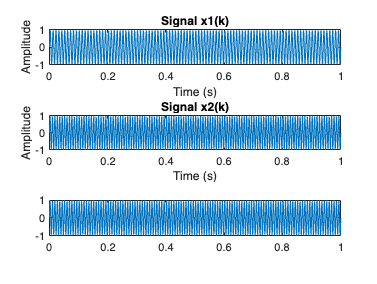

f1 = 100; %Hz
f2 =  120; %Hz
A = 1; % amplitude
t = [0:1/1000:1];
f_s = 1000;
d = 1 - 0; % duration

% f_s = n/(x2-x1) % f_s = n/duration = n/(x2-x1)
% t = [x1:1/f_s:(x2-1)]; 
% so in this case f_s = 1000 -> by reading t definition

% function [x]=generate_sine(frequency,A,fs,duration)
x1 = generate_sine(f1, A, f_s, d);
x2 = generate_sine(f2, A, f_s, d);

**Generate a test signal x3(k) composed of the summation of x1(k) and x2(k). **

x3 = x1 + x2;

**theory:**

**direct method: **computes the power spectral density (PSD) using the Fourier transform of the signal.

Pros: Simple to implement and provides a quick estimate

Cons: Noisy and less accurate with variance that does not decrease with more samples

**indirect method: **first calculates the autocorrelation of the signal and then takes the Fourier transform of the autocorrelation to obtain the PSD.

Pros: More accurate and less noisy with variance that decreases with more samples

Cons: Computationally complex and requires more data for accurate estimation

When estimating the autocorrelation function as part of the indirect method for spectral estimation, you can choose between a biased or an unbiased estimator. The difference lies in how the autocorrelation is computed, affecting the accuracy and bias of the resulting power spectral density (PSD) estimate.

**Biased Autocorrelation**

The biased estimator divides by the total number of samples 𝑁 regardless of the lag 𝑚. This approach tends to smooth the estimate but introduces a bias in the autocorrelation function, especially for larger lags.

Pros

- Smoother estimates

- Less variance

Cons

- Introduces bias

- Can be inaccurate for large lags

**Unbiased Autocorrelation**

The unbiased estimator divides by 𝑁−𝑚, the number of terms in the summation, which adjusts for the decreasing number of terms at larger lags. This approach provides a more accurate estimate of the true autocorrelation but can be noisier.

Pros

- More accurate for larger lags

- Less bias

Cons

- More variance

- Can be noisier

**Calculate and visualize the power spectrum of x1(k), x2(k), x3(k) by using the indirect method, and by fixing the length of the autocorrelation function equal to the length of the signal (MAXLAG =500). **

% Calculate unbiased autocorrelation with 500 lags
% The unbiased option scales the autocorrelation to remove bias from the estimate
R1_x1 = xcorr(x1, 500, 'unbiased');

Unrecognized function or variable 'x1'.

R1_x2 = xcorr(x2, 500, 'unbiased');
R1_x3 = xcorr(x3, 500, 'unbiased');


% Calculate Power Spectral Density (PSD) using FFT and fftshift for unbiased autocorrelation
% fftshift centers the zero frequency component
PSD_x1_R1 = fftshift(abs(fft(R1_x1)));
PSD_x2_R1 = fftshift(abs(fft(R1_x2)));
PSD_x3_R1 = fftshift(abs(fft(R1_x3)));

% Calculate biased autocorrelation with 500 lags
% The biased option does not scale the autocorrelation
R2_x1 = xcorr(x1, 'biased', 500);
R2_x2 = xcorr(x2, 'biased', 500);
R2_x3 = xcorr(x3, 'biased', 500);

% Calculate Power Spectral Density (PSD) using FFT and fftshift for biased autocorrelation
PSD_x1_R2 = fftshift(abs(fft(R2_x1)));
PSD_x2_R2 = fftshift(abs(fft(R2_x2)));
PSD_x3_R2 = fftshift(abs(fft(R2_x3)));

% Frequency vector for plotting
f = linspace(-500, 500, length(R1_x1));

% Plot PSD for x1, x2, x3 using unbiased autocorrelation
figure;
subplot(3,1,1);
plot(f, PSD_x1_R1);
title('PSD of x1 (unbiased)');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(3,1,2);
plot(f, PSD_x2_R1);
title('PSD of x2 (unbiased)');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(3,1,3);
plot(f, PSD_x3_R1);
title('PSD of x3 (unbiased)');
xlabel('Frequency (Hz)');
ylabel('Power');

% Plot PSD for x1, x2, x3 using biased autocorrelation
figure;
subplot(3,1,1);
plot(f, PSD_x1_R2);
title('PSD of x1 (biased)');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(3,1,2);
plot(f, PSD_x2_R2);
title('PSD of x2 (biased)');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(3,1,3);
plot(f, PSD_x3_R2);
title('PSD of x3 (biased)');
xlabel('Frequency (Hz)');
ylabel('Power');

% Comparison plot between unbiased and biased PSD for x3
figure;
plot(f, PSD_x3_R1, 'r');
hold on;
plot(f, PSD_x3_R2, 'b');
title('Comparison of PSD of x3 (unbiased vs biased)');
xlabel('Frequency (Hz)');
ylabel('Power');
legend('Unbiased', 'Biased');
hold off;



% function[x] = generate_sine(A,frequency,fs,duration)
x1=generate_sine(1,100,1000,1);
x2=generate_sine(1,120,1000,1);
%Generate x3 = x1+x2;
x3=x1+x2;

%R1 unbiassed
% 500 points where we calculate (1000 samples(-500:500))
R1_x1=xcorr(x1,'unbiased',500);
R1_x2=xcorr(x1,'unbiased',500);
R1_x3=xcorr(x1,'unbiased',500);
f=linspace(-500,500,length(R1_x1));

PSD_x1_R1=fftshift(abs(fft(R1_x1)));
PSD_x2_R1=fftshift(abs(fft(R1_x2)));
PSD_x3_R1=fftshift(abs(fft(R1_x3)));

%Biased R2
R2_x1=xcorr(x1,'biased',100);
R2_x2=xcorr(x1,'biased',100);
R2_x3=xcorr(x1,'biased',100);


PSD_x1_R2=fftshift(abs(fft(R2_x1)));
PSD_x2_R2=fftshift(abs(fft(R2_x2)));
PSD_x3_R2=fftshift(abs(fft(R2_x3)));

%comparison between both output of the cose
plot(f,PSD_x1_R1);
plot(f,PSD_x2_R1);
plot(f,PSD_x3_R1);

plot(f,PSD_x3_R1,'r');
hold on;
plot(f,PSD_x3_R2,'b');